## ***Problem Statement******: *****Consider a plane slab of large surface area and thickness 0.2m. Find temperature distribution and Rate of heat transfer at different location for given temperature and convection boundary conditions.**

## ***Assumptions******: *****1D, Transient, constant thermal conductivity, no heat generation.**

## ***Parameters*****: **

- **Temperature at far left surface of slab = 373K**

- **Convection condition at far right of the slab = Air at T_infinity = 303K and h= 45 (W/K.m^2)**

- **k = 18 (W/K.m)**

- **L = 0.2m**

- **q_gen = 0 (W/m^3)**

- 
$$\alpha =0\ldotp 000228\;\left(\frac{m^2 }{s}\right)$$


## ***Find*****: **

- **Temperature distribution (done)**

- **Heat transfer flux at different locations (done)**

- **Analytical solution    done **

- **Numerical solution    done **

- **Plot graph comparing analytical and numerical solution   done **

- **determine how much nodes is sufficient for numerical method  **

- **No. of iterations of each selection of nodes  **

- **error graph per iteration **

- **Code time execution for each value of nodes     done **

***1. Setting the parameters of the problem:***

clear
clc

format long  %Large no of float points are used to reduce the trucation error.
N = 5;  % No. of nodes 
L = 0.2;  % Thickness of plane slab
delta_x = L/(N-1);   % Element size
x = 0:delta_x:L;
e = 0.000001;     % error thresold
k_const = 18;       % Thermal conductivity (constant)
h = 45;           % Heat transfer conefficent of air  
T_inf = 303;     % Air temperature 

***2. Analytical Solution: Governing differential equation: ***$\frac{d^2 }{\textrm{d}x^2 }T$= 0

**Boundary conditions :**

- **at x=0, T=373K**

- **at x=0.2 m,  **$-\mathit{\mathbf{k}}*\frac{\mathit{\mathbf{d}}}{\textrm{d}\mathit{\mathbf{x}}}\mathit{\mathbf{T}}=\mathit{\mathbf{h}}*\left(\mathit{\mathbf{T}}-{\mathit{\mathbf{T}}}_{\infty } \right)\;$**at x = 0.2m **

**Solving above Temperature distribution will be: **$\mathit{\mathbf{T}}\;\left(\mathit{\mathbf{K}}\right)=-116\ldotp 667*\mathit{\mathbf{x}}+373$

**solving for x=0.2, minimum temperature will be T = 349.666K**

**Heat flux **$\dot{\left(\frac{Q}{A}\right)}$** :   **$-k*\frac{\textrm{d}}{\textrm{d}x}T=2100\ldotp 1\left(\frac{W}{m^2 }\right)$ , which is constant for all x for this problem

x_analytical = linspace(0,.2,20);  % position long slab thickness
T_analytical = 373 - (116.67*x_analytical); % exact temperatures at these positions
Q_dot_flux_analytical = -k_const*(T_analytical(end) - T_analytical(1))/L; %calculates heat flux

***3. Numerical Solution: Discritizing the governing equation : ***$\frac{{\textrm{d}}^2 }{\textrm{d}x^2 }T$ = 0

- **For first node: T = 373K**

- **For nodes 2 to N-1 : **$T_m =\frac{T_{m+1} +T_{m-1} }{2}$

- **For last node N: **$T_N =\frac{k*T_{N-1} +T_{\infty } *h*\Delta x}{k+h*\Delta x}$

**Heat flux at a particular location (same for each point) : **$-k*\frac{\left(T_{n+1} -T_n \right)}{\Delta x}=2100\ldotp 1\;\left(\frac{W}{m^2 }\right)$

T_guess = zeros(1,N);  % Initial guess for gauss-seidel iteration 
T_guess(1) = 373;

T_current = T_guess;

% First iteration
tic;
i = 0;
Max_Error = 0;
[T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_current, N, delta_x, h, k_const, T_inf, i, Max_Error); 

Iteration no.: 1
     1.865000000000000e+02




% iterating until the solution converges (error goes below the thresold value)
while max(AbsoluteError) > e
    [T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_new, N, delta_x, h, k_const, T_inf, i, Max_Error);
end

Iteration no.: 2
   1.0e+02 *

   1.865000000000000   0.608680555555556

Iteration no.: 3
   1.0e+02 *

   1.865000000000000   0.608680555555556   0.480976080246914

Iteration no.: 4
   1.0e+02 *

   1.865000000000000   0.608680555555556   0.480976080246914   0.386624014060357

Iteration no.: 5
   1.0e+02 *

   1.865000000000000   0.608680555555556   0.480976080246914   0.386624014060357   0.311703115474013

Iteration no.: 6
   1.0e+02 *

   1.865000000000000   0.608680555555556   0.480976080246914   0.386624014060357   0.311703115474013   0.251428051940973

Iteration no.: 7
   1.0e+02 *

   1.865000000000000   0.608680555555556   0.480976080246914   0.386624014060357   0.311703115474013   0.251428051940973   0.202826147336028

Iteration no.: 8
   1.0e+02 *

  Columns 1 through 7

   1.865000000000000   0.608680555555556   0.480976080246914   0.386624014060357   0.311703115474013   0.251428051940973   0.202826147336028

  Column 8

   0.163621577823919

Iteration no.: 9
   1.0e+02 *

 


for n = 2:N
    if n == N
        Q_dot_flux_numerical(N) = h*(T_new(n) - T_inf);
    else
        Q_dot_flux_numerical(n-1) = -k_const*(T_new(n) - T_new(n-1))/delta_x;
    end 
    
end
disp("Elapsed time is " + toc+ "seconds")

Elapsed time is 0.93159seconds


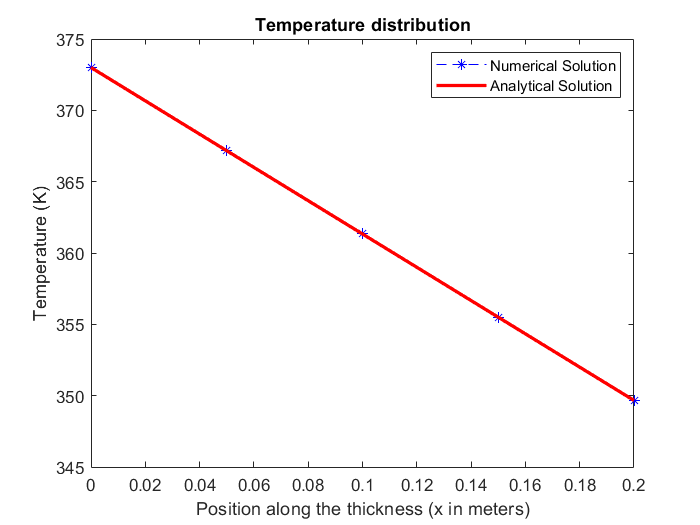


% Temperature distribution plot 
plot(x, T_new, "b--*")
hold on 
plot(x_analytical, T_analytical, "r", 'LineWidth',2 )
xlabel("Position along the thickness (x in meters)")
ylabel("Temperature (K)")
title("Temperature distribution")
legend("Numerical Solution", "Analytical Solution")
hold off

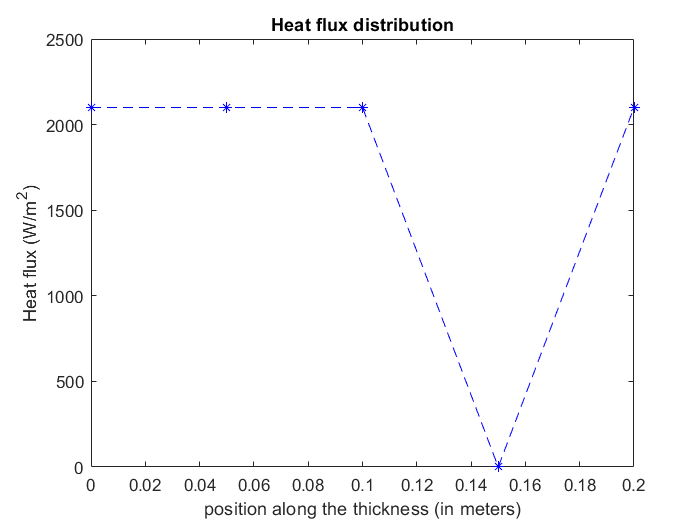


% Heat flux distribution plot
plot(x, Q_dot_flux_numerical, "b--*")
hold on 
xlabel("position along the thickness (in meters)")
ylabel("Heat flux (W/m^2)")
title("Heat flux distribution")
hold off 


%error plot per iteration 
Iterations = 1:86

Iterations =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


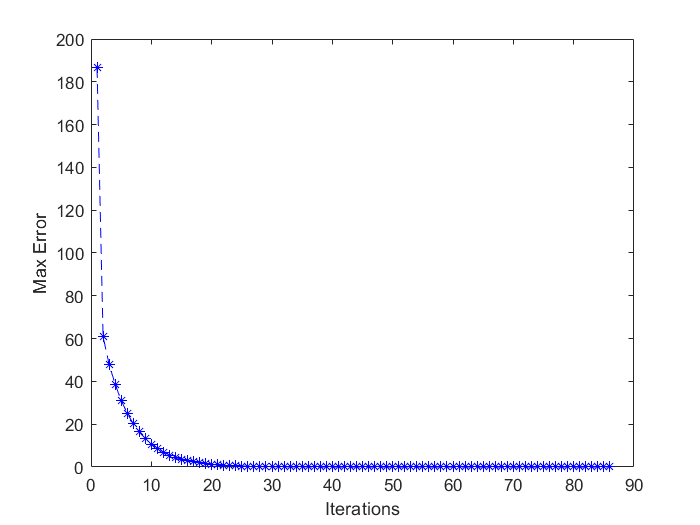

plot(Iterations, Max_Error, "b--*")
hold on 
plot(Iterations, e,"r", "LineWidth", 2)
xlabel("Iterations")
ylabel("Max Error")
hold off 

format short 

***Numerical iterator based on Gauss-Siedel Method***

function [T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_current, N, delta_x, h, k_const, T_inf, i, Max_Error)
    T_new(1) = 373; % far left node is at constant temperature 
    for n = 2:N
        if n < N % For inner nodes 
            % use of latest value for the calculation of next temperature
            % at different position 
            T_new(n) = (T_new(n-1) + T_current(n+1))*0.5; 
            
        elseif n == N  % For Node at the far right surface influenced by convection
            T_new(n) = (k_const*T_new(n-1) + T_inf*h*delta_x)/(k_const + h*delta_x);
        end
        
    end
    %disp(T_new)
    i = i +1;
    disp("Iteration no.: " + i)
    AbsoluteError = abs(T_new - T_current); % absolute error at each node
    Max_Error(i) = max(AbsoluteError);
    disp(Max_Error)
end

